# Habeeb and Brian

Home work 3

clc
close all

global G; global h; global n; global x; global a; global b;
warning('off','all')
data = load('gravprob.mat');
x = data.x;
d = data.obs;

mtrue = 2.*[80 80 80 80 80 80 85 85 85 85 90 95 100 105 110 120 135 150 160 170]';

sig1 = 1e-12;
sig2 = 1e-14;

tol = 1e-6;

### No.1

The Jacobian was coded based on the centered difference approach as follows: 1). Created an empty container, J, of dimension (20 by 20)  to store a (20 by 1) vector: $$\frac{(G(m + he_j) - G(m - he_j))}{(2*h)}$$ at every iteration $j ~\forall ~ j \in [1,n]$, forming a (20 by 20)  Jacobian matrix. This is posible since $m$ and $e_j$ are (20 by 1) vectors, with $G(m \pm he_j)$, a function returning a (20 by 1) vector as well. The vector $e_j$ is a standard basis vector whose single non zero element one is update at every $j$ iteration.

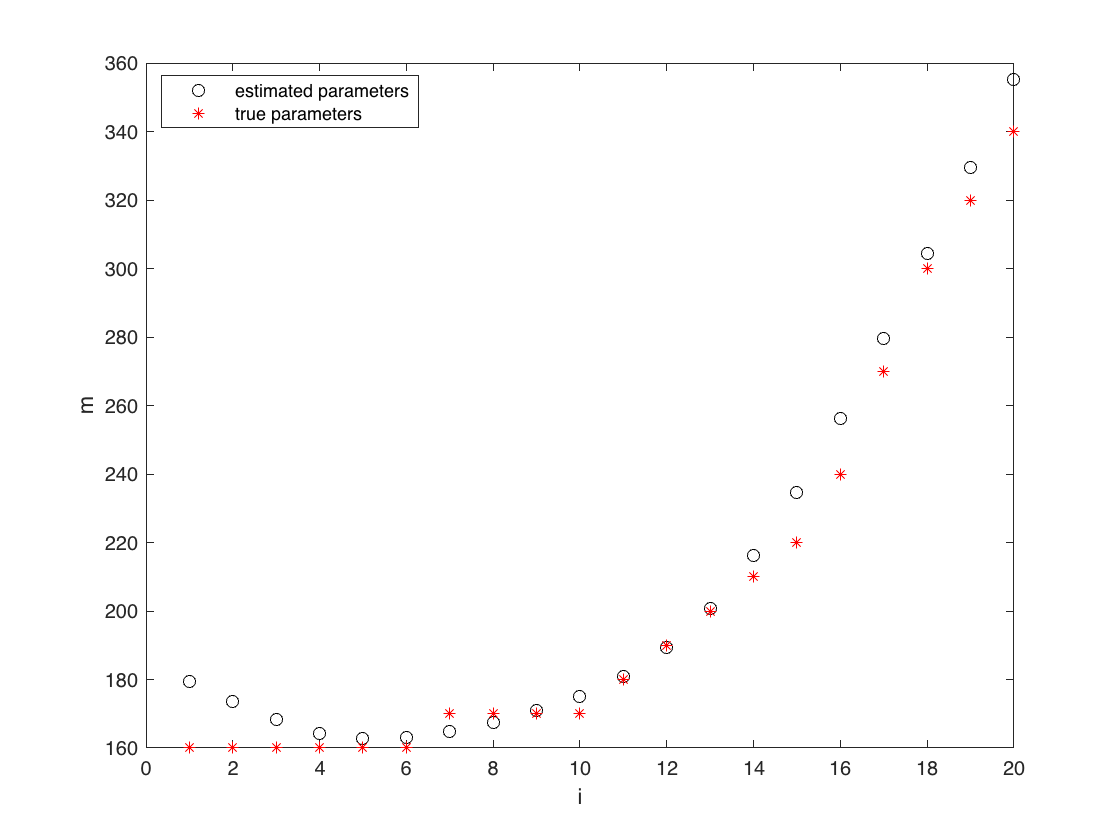

h = 0.8;
a = 0; b = 1000;
n = 20;

% generate roughening matrices
L2 = get_l_rough(n,2);

mo = 200*ones(n,1); %initial estimates
drho = 200; %density peturbations

G = @(m) g(m,drho); %calling the function G
J = @(m) jac(m); %calling the function Jacobian

mn1 = occam(G, J, L2, d, mo, 0); %calling occam model

%plots
figure(1)
plot(mn1,'ko'); hold on
plot(mtrue,'r*')
ylabel('m');xlabel('i')
legend('estimated parameters', 'true parameters',Location='best')

We had to downsize the value of the initial estimates from 400 to 200 for all the parameters inorder to achieve a reasonable solution, this was due to the nature of the intergration rule used as its not good enough to yeild the right approximates. On doing that we where able to obtain a close fit of the true parameter estimates as shown in the figure above.

### No.1 d)

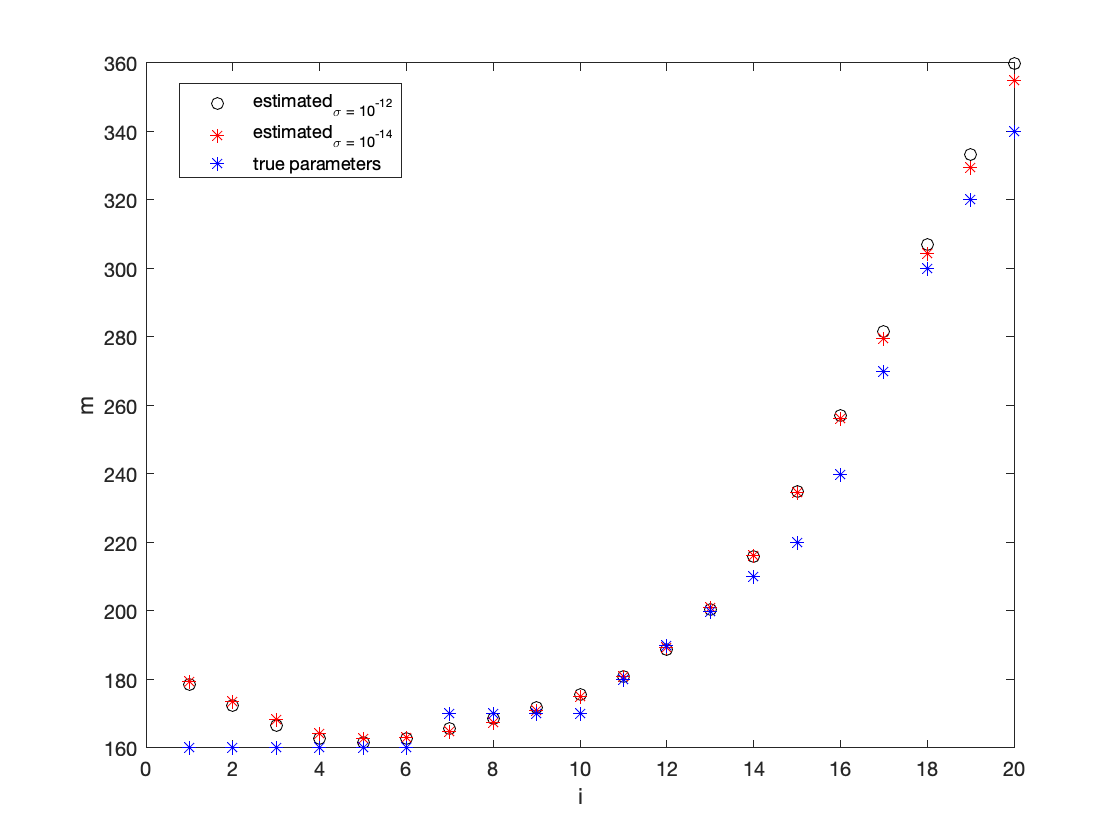

steploc = 650; low = 280; high = 400; %spike limits
mtest1 = spike(low,high,steploc); %spike model

noise = sig1*randn(n,1); %generating noise
dn1 = d + noise; %data subjected to noise
m1 = occam(G, J, L2, dn1, mtest1', 0); %calling occam model

noise = sig2*randn(n,1); %generating noise
dn2 = d + noise; %data subjected to noise
m2 = occam(G, J, L2, dn2, mtest1', 0);  %calling occam model

%plots
figure(2)
plot(m1,'ko'); hold on
plot(m2,'r*');
plot(mtrue,'b*')
ylabel('m');xlabel('i')
legend('estimated_{\sigma = 10^{-12}}', 'estimated_{\sigma = 10^{-14}}', 'true parameters',Location='best')

According to the plot above we somehow achieved good resolution of the true parameter estimates at the points where the inverse solution coincided with the true solution,  however, the spiked model parameters are greater than the first four elements of the true parameter estimates, hence yeilding poor resolution at those points. And outside the first four elements/features, other features appeared to be real and well captured. The magnitude of $\sigma$ has very less impact to the noise subjected to the data, and the spike model, since the solution coincide at all points. Although other varaibles like the step size used in the Jacobian matrix, $\alpha$ used in the occam model and the initial estimate high influence the inverse solution.

### No.1 e)

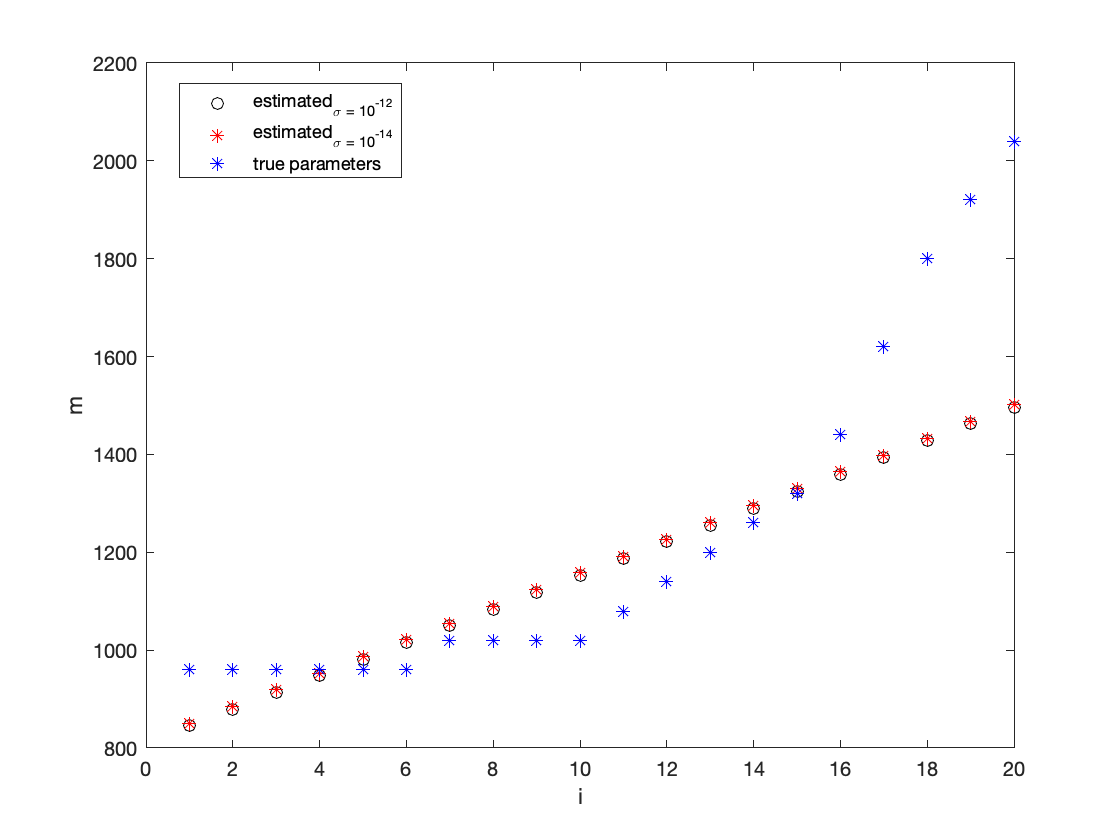

drho = 900; G = @(m) g(m,drho); %upgrading the value of drho
steploc = 650; low = 1280; high = 1400; %spike limits

%new mtrue
mtru = 12.*[80 80 80 80 80 80 85 85 85 85 90 95 100 105 110 120 135 150 160 170]'; 
mtest2 = spike(low,high,steploc); %new spike model

noise = sig1*randn(n,1); %generating the noise
dn1 = G(mtru) + noise; %data subjected to noise
me1 = occam(G, J, L2, dn1, mtest2', 0); %calling occam model

noise = sig2*randn(n,1); %generating the noise
dn2 = G(mtru) + noise; %data subjected to noise
me2 = occam(G, J, L2, dn2, mtest2', 0); %calling occam model

%plots
figure(3)
plot(me1,'ko'); hold on
plot(me2,'r*');
plot(mtru,'b*');
ylabel('m');xlabel('i')
legend('estimated_{\sigma = 10^{-12}}', 'estimated_{\sigma = 10^{-14}}', 'true parameters',Location='best')

When the density pertubation was changed to $1000~m$ depth, this inturn increased the density pertubation and the lower and upper boundaries of the spike model test parameters. W had to adjust the $m_{true}$ to the order of 1000 inorder to be able to use the occam model to retrive it, however due to the deep depth, the resolution is way so poor as seen from the figure above. This may be due to obstacles influencing the signal under the surface since it has to travel a penetrate along depth and bounce back in the same depth with result which is high drainged by the obstacles along the way. The solution isn't so much affected by the noise (value of $\sigma$) subjected to the data, as both solutions almost coincide with each other. Although other varaibles like the step size used in the Jacobian matrix, $\alpha$ used in the occam model and the  initial estimate high influence the inverse solution.

### No.2

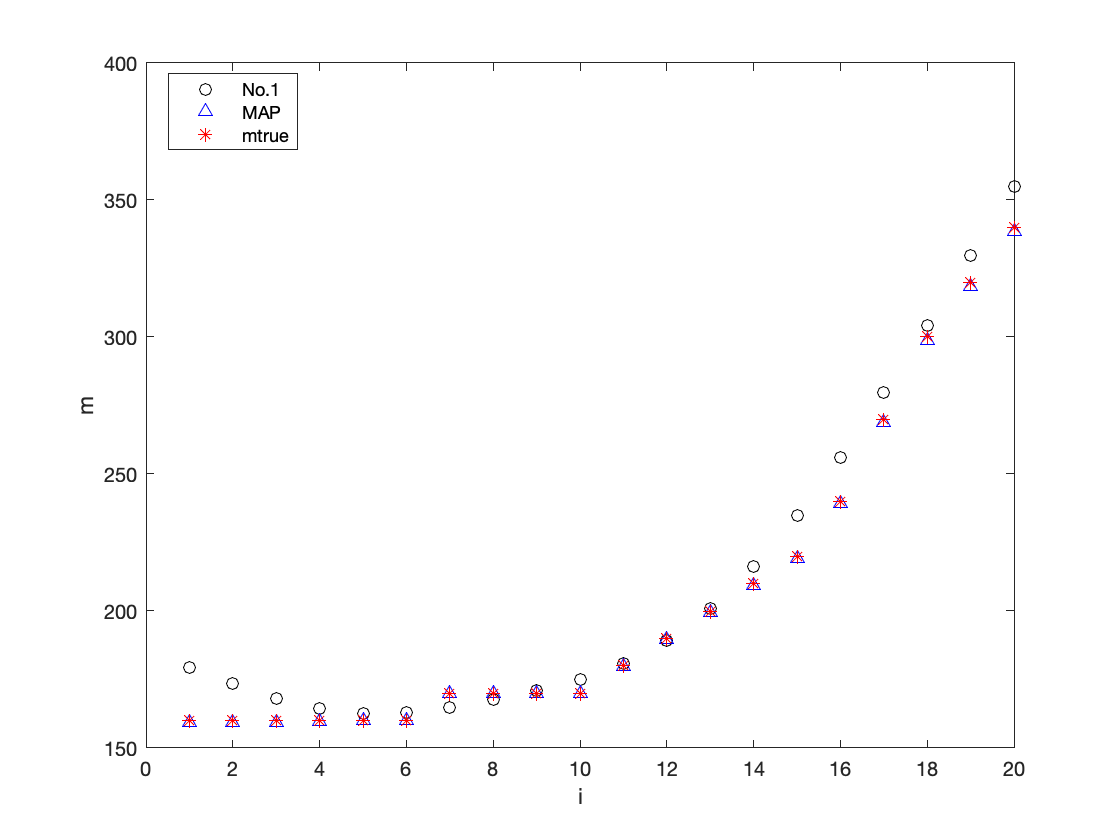

maxiter = 1e6; %maxiter

drho = 200; G = @(m) g(m,drho); %dhro and the model

func = @(CD,CM,mprior,m) [(CD^(-0.5))*G(m);(CM^(-0.5))*m] - [(CD^(-0.5))*d;(CM^(-0.5))*mprior]; %standard least square function
Jac = @(CD,CM,m) [(CD^(-0.5))*J(m); CM^(-0.5)]; %standard Jacobian

tmean = 2.*[80 80 80 80 80 80 85 85 85 85 90 95 100 105 110 120 135 150 160 170]'; %new true estimated mean

mprior = tmean -  0.005*tmean; %mprior
stdm =  0.005*tmean; %
CM = diag(stdm.^2); %covariance matrix

%noise in the data
stdd = G(tmean) - d;

CD = diag(stdd.^2); %data covariance matrix

[MAP, iter] = lm(CD,CM,func, Jac, mprior, tol, maxiter); %calling the map function

%plots
figure(4)
plot(mn1,'ko'); hold on
plot(MAP,'b^');
plot(mtrue,'r*');
ylabel('m');xlabel('i')
legend('No.1', 'MAP','mtrue',Location='best')

The MAP solution approximates the true solution much better than the occam model in part 1, as seen in the graph above.  This might be caused due to the value of the initial estimate and $\alpha$ used in the occam model which might not have been chosed properly. The MAP solution depended on the chosen values of the mean and covariance, and these where choosen basing on how welll the MAP model was fitting the true parameters.

The non-linear formulation was written as a regular least squares problem as follows:

           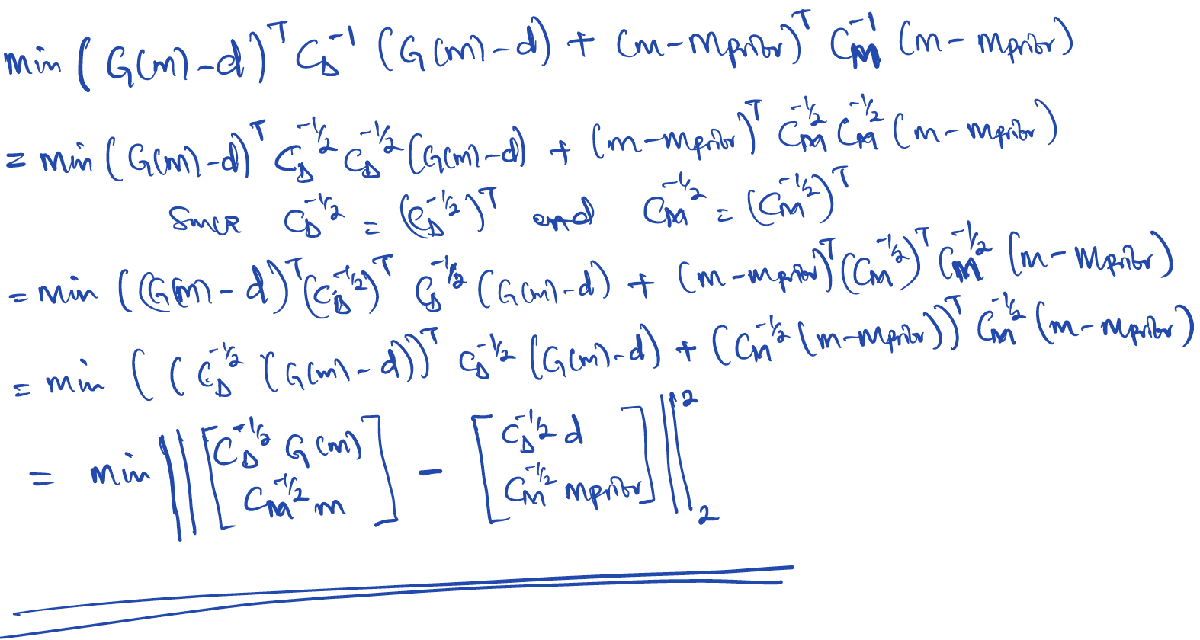

function [J] = jac(m) %formulation of the Jacobian
    global G; global h; global n;
    J = [];
    for j=1:n
        ej = zeros(n,1);
        ej(j) = 1; 
        J = [J (G(m + h.*ej) - G(m - h.*ej))./(2*h)];
    end
end

%formulation of the G
function [G] = g(m,drho) 
    global n; global x; global a; global b;
    R = 6.67428e-11; % Newton's gravitational constant
    dxc = (b-a)/(n-1); 
  
    G = zeros(n,1);
    gg = @(xc,x,m) (((R*drho).*m)./((xc' - x).^2 + m.^2).^(3/2));
    for j = 1:n
        xj = x(j);
        for i = 1:n
             xc = a + (i-1)*dxc; %creating xc using left end points
             G(j) = G(j) + (gg(xc,xj,m(i)))*dxc; %creating G using left end points
        end
    end

end

%spike model
function [mtest1] = spike(low,high,steploc)
    global a; global b; global n;
    dxc = (b-a)/(n-1);
    xc = [];
    for j = 1:n
        xc = [xc a + (j-1)*dxc]; %form xc
    end
    
    xc = a:dxc:b;
    idx = find(xc <= steploc); %finding the step location
    mtest1 = [];
    for i = 1:n
        if i <= idx(end)
            mtest1 = [mtest1 low];
        else
            mtest1 = [mtest1 high];
        end
    end
end